clear;clc;close all;

R = 10; L = 0.01; C = 1e-6;
s = tf('s');
G = 1 / (L*C*s^2 + R*C*s + 1);

% 滞后部分,在极低频提供高增益，但不影响中高频
w_lag = 20;
beta = 10;
z_lag = w_lag / 5;
p_lag = z_lag / beta;
C_lag = (s + z_lag) / (s + p_lag);

% 超前部分.在截止频率附近提供 57° 的正相位
w_lead = 14286;  % 原截止频率
phi_m = 57;
a = (1 + sind(phi_m)) / (1- sind(phi_m));
z_lead = w_lead / sqrt(a);
p_lead = w_lead * sqrt(a);
K_lead = sqrt(a);
C_lead = K_lead * (s + z_lead) / (s + p_lead);

C_total = C_lead * C_lag;

G_open = C_total * G;

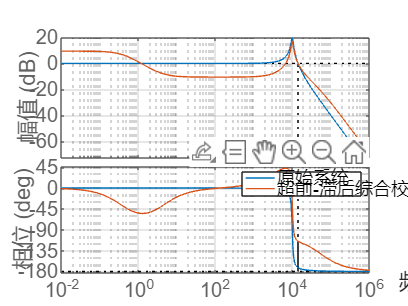

figure;
margin(G); hold on;
margin(G_open);
legend('原始系统', '超前-滞后综合校正后');
title('超前-滞后综合校正前后的 Bode 图对比');
grid on; hold off;

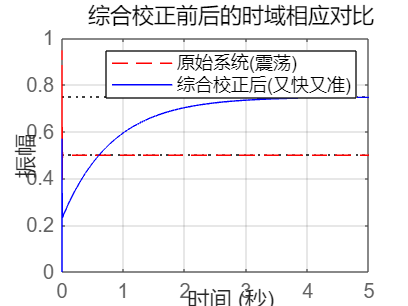


T_old = feedback(G,1);
T_new = feedback(G_open, 1);

figure;
step(T_old, 'r--', T_new, 'b-');
legend('原始系统(震荡)', '综合校正后(又快又准)');
title("综合校正前后的时域相应对比");
grid on;